## Demodulación Digital en Banda Base  

### Introducción

En esta práctica veremos cómo modelar las diferentes técnicas de demodulación de señales  digitales estudiadas en teoría. Para ello, partiendo de varias señales recibidas, veremos los  valores de salida en caso de utilizar un banco de correladores o un banco de filtros adaptados.  Además, veremos también el efecto que tiene el ruido introducido por el canal sobre los valores  obtenidos por estos bloques del receptor.   En esta primera sesión de laboratorio trabajaremos con las señales mostradas en la Figura 1  como señales moduladas 

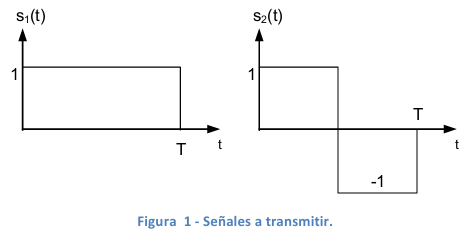

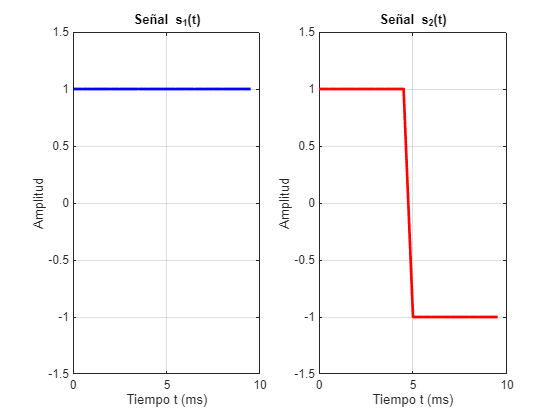

% --- Parámetros del sistema ---
T  = 10e-3;      % Tiempo de símbolo: 10 ms
Ts = T / 20;     % Periodo de muestreo: 0.5 ms (20 muestras por símbolo)

% --- Llamada a la función modular ---
[s1, s2, t] = generar_senales_fig1(T, Ts);

% --- Representación gráfica (Figura 1) ---
figure('Name', 'Figura 1 - Señales a transmitir', 'Color', 'w');

% Gráfica de s1(t)
subplot(1, 2, 1);
plot(t * 1e3, s1, 'b-', 'LineWidth', 2);
grid on;
title('Señal s_1(t)');
xlabel('Tiempo t (ms)');
ylabel('Amplitud');
xlim([0, T * 1e3]);
ylim([-1.5, 1.5]);

% Gráfica de s2(t)
subplot(1, 2, 2);
plot(t * 1e3, s2, 'r-', 'LineWidth', 2);
grid on;
title('Señal s_2(t)');
xlabel('Tiempo t (ms)');
ylabel('Amplitud');
xlim([0, T * 1e3]);
ylim([-1.5, 1.5]);

### 2.1.Demodulación por correlación.

El demodulador por banco de correladores se puede implementar de manera discreta en el  tiempo mediante el muestreo de la señal recibida y realizando la correlación con la versión  muestreada de cada una de las componentes de la base de la constelación.  

Hemos elegido la demodulación por correlación frente al filtro adaptado porque ambos son matemáticamente equivalentes en el instante de muestreo t=T*t*=*T*, proporcionando la misma probabilidad de error bajo canal AWGN. A nivel práctico en MATLAB, el correlador es más directo y eficiente: no requiere calcular convoluciones ni expandir el vector temporal (mantiene las L=20*L*=20 muestras exactas del símbolo), permitiendo visualizar de forma clara cómo se acumula la energía a lo largo del intervalo [0,T][0,*T*] mediante una simple suma acumulativa (`cumsum`).

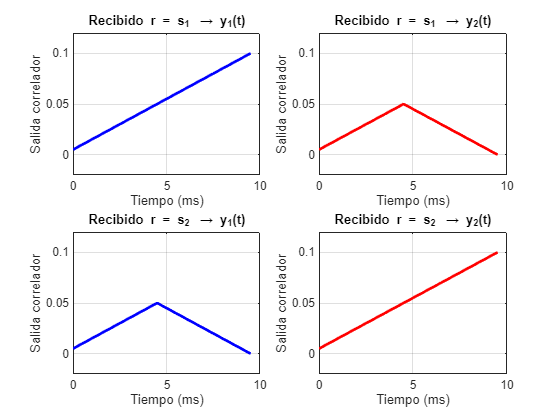

%% EJERCICIO 2.1: DEMODULACIÓN POR BANCO DE CORRELADORES (SIN RUIDO)

% --- Parámetros base ---
T  = 10e-3;      % 10 ms = 0.01 s
Ts = T / 20;     % 0.5 ms
L  = T / Ts;     % 20 muestras
t_ms = (0:L-1) * Ts * 1e3; % Eje temporal en ms (0 a 9.5 ms)

% Señales elementales s1 y s2
[s1, s2, ~] = generar_senales_fig1(T, Ts);

% --- CASO A: Se transmite s1(t) (r = s1) ---
rA = s1;
[y1_r1, y2_r1] = correlatorType(T, Ts, rA);

% --- CASO B: Se transmite s2(t) (r = s2) ---
rB = s2;
[y1_r2, y2_r2] = correlatorType(T, Ts, rB);

% --- REPRESENTACIÓN GRÁFICA (Escala 0 a 0.1) ---
figure('Name', 'Ejercicio 2.1 - Salida de los Correladores', 'Color', 'w');

% Caso A: Recibido s1
subplot(2, 2, 1);
plot(t_ms, y1_r1, 'b-', 'LineWidth', 2); grid on;
title('Recibido r = s_1 \rightarrow y_1(t)');
xlabel('Tiempo (ms)'); ylabel('Salida correlador');
xlim([0, 10]); ylim([-0.02, 0.12]);
yticks([0, 0.05, 0.1]);
yticklabels({'0', '0.05', '0.1'});

subplot(2, 2, 2);
plot(t_ms, y2_r1, 'r-', 'LineWidth', 2); grid on;
title('Recibido r = s_1 \rightarrow y_2(t)');
xlabel('Tiempo (ms)'); ylabel('Salida correlador');
xlim([0, 10]); ylim([-0.02, 0.12]);
yticks([0, 0.05, 0.1]);
yticklabels({'0', '0.05', '0.1'});

% Caso B: Recibido s2
subplot(2, 2, 3);
plot(t_ms, y1_r2, 'b-', 'LineWidth', 2); grid on;
title('Recibido r = s_2 \rightarrow y_1(t)');
xlabel('Tiempo (ms)'); ylabel('Salida correlador');
xlim([0, 10]); ylim([-0.02, 0.12]);
yticks([0, 0.05, 0.1]);
yticklabels({'0', '0.05', '0.1'});

subplot(2, 2, 4);
plot(t_ms, y2_r2, 'r-', 'LineWidth', 2); grid on;
title('Recibido r = s_2 \rightarrow y_2(t)');
xlabel('Tiempo (ms)'); ylabel('Salida correlador');
xlim([0, 10]); ylim([-0.02, 0.12]);
yticks([0, 0.05, 0.1]);
yticklabels({'0', '0.05', '0.1'});

a) Son resultados lógicosm la salida Y1 para S1 crece continuamente debido a que correla hasta llegar en T a 1, Al correlarse con S2 solo es creaciente cuando S2 tiene valor positivo. Lo mismo ocurre con S2 durante las fases contrarias. La amplitud tiene esos valores ya que es la energía de la señal

b) El momento ideal sería T, ya que es el máximo valor de energía y por lo tanto el mejor momento para asignar símbolo

### Ejercicio 2.2 

Modifique la función anterior añadiendo un ruido blanco gaussiano sobre la señal “recibida”.  Vuelva a representar la salida de los correladores en función del tiempo para ambos símbolos  de entrada. Comente las gráficas obtenidas. 

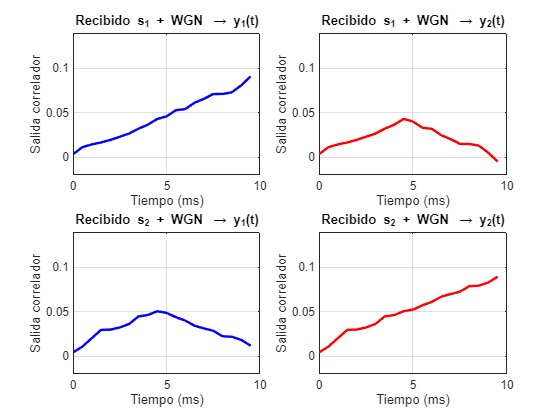

%% EJERCICIO 2.2: CORRELADORES CON RUIDO WGN (ESCALA ACTUALIZADA)

rng(1, "twister");
sigma = 0.5;

% Simulación con las señales y ruido
[y1_r1_n, y2_r1_n] = correlatorNoise(T, Ts, s1, sigma);
[y1_r2_n, y2_r2_n] = correlatorNoise(T, Ts, s2, sigma);

figure('Name', 'Ejercicio 2.2 - Correladores con WGN', 'Color', 'w');

% Caso A: Recibido s1
subplot(2, 2, 1);
plot(t_ms, y1_r1_n, 'b-', 'LineWidth', 1.8); grid on;
title('Recibido s_1 + WGN \rightarrow y_1(t)');
xlabel('Tiempo (ms)'); ylabel('Salida correlador');
xlim([0, 10]); ylim([-0.02, 0.14]);
yticks([0, 0.05, 0.1]);
yticklabels({'0', '0.05', '0.1'});

subplot(2, 2, 2);
plot(t_ms, y2_r1_n, 'r-', 'LineWidth', 1.8); grid on;
title('Recibido s_1 + WGN \rightarrow y_2(t)');
xlabel('Tiempo (ms)'); ylabel('Salida correlador');
xlim([0, 10]); ylim([-0.02, 0.14]);
yticks([0, 0.05, 0.1]);
yticklabels({'0', '0.05', '0.1'});

% Caso B: Recibido s2
subplot(2, 2, 3);
plot(t_ms, y1_r2_n, 'b-', 'LineWidth', 1.8); grid on;
title('Recibido s_2 + WGN \rightarrow y_1(t)');
xlabel('Tiempo (ms)'); ylabel('Salida correlador');
xlim([0, 10]); ylim([-0.02, 0.14]);
yticks([0, 0.05, 0.1]);
yticklabels({'0', '0.05', '0.1'});

subplot(2, 2, 4);
plot(t_ms, y2_r2_n, 'r-', 'LineWidth', 1.8); grid on;
title('Recibido s_2 + WGN \rightarrow y_2(t)');
xlabel('Tiempo (ms)'); ylabel('Salida correlador');
xlim([0, 10]); ylim([-0.02, 0.14]);
yticks([0, 0.05, 0.1]);
yticklabels({'0', '0.05', '0.1'});

**Comentario de las gráficas con WGN:**

- Al añadir ruido blanco gaussiano de media nula (μ=0*μ*=0), las trayectorias de salida dejan de ser rectas perfectas y muestran un rizado aleatorio.

- A pesar de la contaminación, la integración temporal del correlador ejerce un efecto de filtrado que promedia las fluctuaciones rápidas del ruido.

- En el instante de decisión t=10 ms*t*=10 ms, la salida acumulada fluctúa en torno a su valor medio teórico (0.010.01 en la rama correcta y 00 en la ortogonal). Si la potencia del ruido fuera suficientemente elevada, las fluctuaciones aleatorias podrían provocar que la rama incorrecta supere a la correcta, dando lugar a un error de detección de símbolo.

## 3. Salida del demodulador

### Ejercicio 3.1  

Con referencia a la Figura 2, modifique los demoduladores anteriormente implementados  (correlador o filtro adaptado) para que devuelvan el valor correspondiente a la salida  muestreada al final del periodo de símbolo, es decir 𝑟1 y 𝑟2 en la Figura 2: para cada periodo de  la señal de entrada se genera una muestra a la salida del demodulador S1 y otra a la salida del  demodulador S2. 

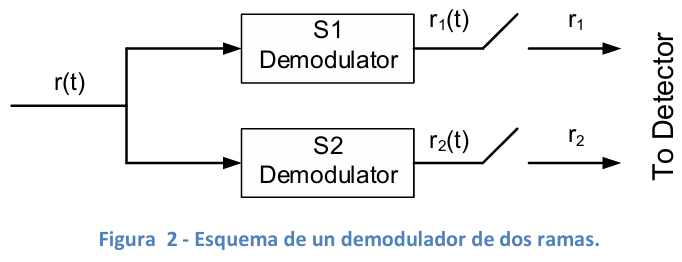

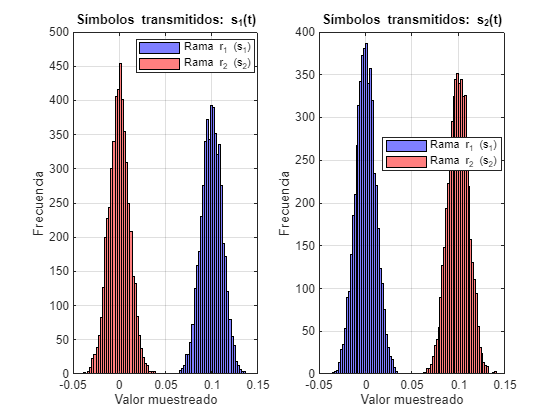

%% EJERCICIO 3.1: SALIDA MUESTREADA DEL DEMODULADOR E HISTOGRAMAS

Nsymb = 5000;    % Muestras estadísticas
sigma = 0.5;     % Desviación típica del ruido
L = round(T / Ts);

rng(1, "twister");

% --- Experimento 1: Enviamos símbolos s1 ---
s1_rep = repmat(s1, 1, Nsymb);
ruido1 = sigma * randn(size(s1_rep));
r_total_s1 = s1_rep + ruido1;

[r1_s1, r2_s1] = demodulador_muestreado(r_total_s1, T, Ts);

% --- Experimento 2: Enviamos símbolos s2 ---
s2_rep = repmat(s2, 1, Nsymb);
ruido2 = sigma * randn(size(s2_rep));
r_total_s2 = s2_rep + ruido2;

[r1_s2, r2_s2] = demodulador_muestreado(r_total_s2, T, Ts);

% --- GRÁFICAS DE LOS HISTOGRAMAS ---
figure('Name', 'Ejercicio 3.1 - Histogramas', 'Color', 'w');

% Transmisión de s1
subplot(1, 2, 1);
histogram(r1_s1, 40, 'FaceColor', 'b', 'FaceAlpha', 0.5, 'DisplayName', 'Rama r_1 (s_1)');
hold on;
histogram(r2_s1, 40, 'FaceColor', 'r', 'FaceAlpha', 0.5, 'DisplayName', 'Rama r_2 (s_2)');
hold off;
grid on;
title('Símbolos transmitidos: s_1(t)');
xlabel('Valor muestreado'); ylabel('Frecuencia');
legend('Location', 'best');
xlim([-0.05, 0.15]);
xticks([-0.05, 0, 0.05, 0.1, 0.15]);
xticklabels({'-0.05', '0', '0.05', '0.1', '0.15'});

% Transmisión de s2
subplot(1, 2, 2);
histogram(r1_s2, 40, 'FaceColor', 'b', 'FaceAlpha', 0.5, 'DisplayName', 'Rama r_1 (s_1)');
hold on;
histogram(r2_s2, 40, 'FaceColor', 'r', 'FaceAlpha', 0.5, 'DisplayName', 'Rama r_2 (s_2)');
hold off;
grid on;
title('Símbolos transmitidos: s_2(t)');
xlabel('Valor muestreado'); ylabel('Frecuencia');
legend('Location', 'best');
xlim([-0.05, 0.15]);
xticks([-0.05, 0, 0.05, 0.1, 0.15]);
xticklabels({'-0.05', '0', '0.05', '0.1', '0.15'});